% location = "./"
% directory = dir(location)
% disp(directory)

location = ".\Project2\Images\train_images\Set1\";
curr_img = imread(location + "1.jpg");
next_img = imread(location + "2.jpg");

    a=dir(location + '*.jpg');
    num_images=size(a,1);
%     tforms(num_images) = projective2d(eye(3));
    imageSize = zeros(num_images,2);
    prev_descriptors = 0;
    threshold = 200;

    
    % grayscale
     curr_img_grayscale = rgb2gray(curr_img);
     next_img_grayscale = rgb2gray(next_img);

     curr_img_corners = cornermetric(curr_img_grayscale);
     next_img_corners = cornermetric(next_img_grayscale);
     
     % imregional 
     curr_img_maxes = imregionalmax(curr_img_corners);
     next_img_maxes = imregionalmax(next_img_corners);

     % ANMS
     [curr_img_x_best, curr_img_y_best] = ANMS(curr_img, curr_img_maxes, curr_img_corners)

curr_img_x_best =     33   503   282    18   427   289   151   395   232   143   576   594   362   363   465   289   431    50   570   552   209   448   586   369    10   228   286   449   179   216   494   416   590   600   432   118   192   124   257   531    64   541   185    32   536    37   449   107   204   224


curr_img_y_best =    450   195   419   222   417   152   199   297   299    73   289   447    53   151    33    55   167   284   178    29   180   105   347   417   330   417   300   297   299   104   364    41   400    39   359   330     8   235    25   228   161   350    57   136   447   410   259   366   262    40


     [next_img_x_best, next_img_y_best] = ANMS(next_img, next_img_maxes, next_img_corners)

next_img_x_best =    414   462   221    61   237   388   223   131     1    37   361   564   346   180   475   111   570   530    37   599   358   498   275    42    99   281    25   552   582   582   414   259   373   543   530   583    84   373   263   409   248    17   392   445   254   139   193    33   169     3


next_img_y_best =    191   399   188   261   432    72    71   450   448    60   403   231   282   282   250     3    59     4   348   407   190    72   190   163   137   449   232   450   168   105   137   281   444   405   129    15   227   228   401   407    33   271   293    34   325    33    33    15   450   142



     % Display 
%       displayANMS(curr_img, curr_img_x_best, curr_img_y_best);
%       displayANMS(next_img, next_img_x_best, next_img_y_best);
     % descriptor
    curr_img_descriptors = feature_descriptors(curr_img_grayscale, curr_img_x_best, curr_img_y_best)

curr_img_descriptors =          0    1.2364    1.9840         0    0.8527    1.5933    1.3921   -1.6641   -2.0758    1.1095   -0.6103         0    1.0733    1.1358   -1.3247    2.0512    1.0557    0.9422    1.5814    1.3796    1.4230    0.6547         0    0.1151         0    0.1880   -2.0409   -1.7976   -1.4314    1.9083   -1.3532   -1.6829         0         0    0.0331    2.2252         0    2.3636    1.1202   -1.0504    0.7070    0.5148    2.5115    0.5826         0    1.5211    1.3646    1.6832    1.5219    0.7640
         0    0.8644    2.0214         0    0.7018    1.4941    1.3616   -1.3599   -1.6063    1.1095   -1.3871         0    0.1574    0.7233   -1.3247    2.0512    0.7633    0.5692    1.5324    1.3796    1.3917   -0.0211         0   -0.0219         0    0.7203   -1.5767   -1.4956   -1.1953    1.0233   -1.4506   -1.6829         0         0    0.0331    1.9792         0    2.4222    1.1202   -0.9931   -0.1979    0.7976    2.5115    0.5826         0    1.4608    1.1447    1.

    next_img_descriptors = feature_descriptors(next_img_grayscale, next_img_x_best, next_img_y_best)

next_img_descriptors =     1.2813   -0.4402    0.3268   -2.0969         0   -1.8285   -2.2668         0         0    0.7334   -1.6264    1.2080    1.5312   -1.3811    1.9924         0    0.4546         0   -2.8618         0    0.3823   -1.7435    2.1279    1.4985    1.6241         0    0.7068         0         0         0    0.7725   -1.4908         0   -1.6705    0.8978         0    0.5345    0.3707   -1.6482   -1.6088    1.4294         0   -1.4276    1.3070   -1.2537    0.6055    1.4337         0         0         0
    1.1526   -1.1147    0.5685   -2.1415         0   -1.4905   -1.8742         0         0    0.2358   -1.1344    1.6159    1.5312   -0.8462    1.7133         0   -0.2898         0   -1.2612         0    0.2287   -1.4588    2.0147    1.3209    1.6241         0    1.3705         0         0         0    0.7725   -1.5748         0   -1.1530    1.1150         0    0.4724    0.8472   -1.1498   -1.1075    1.1674         0   -0.1663    1.1051   -0.8427    0.5054    1.1847      

    
    % matching points
    threshold = 5;
    [matchedDescriptors1, matchedDescriptors2, matchedp1X, matchedp1Y, matchedp2X, matchedp2Y] = getMatchedPoints(curr_img_descriptors, next_img_descriptors, curr_img_x_best, curr_img_y_best, next_img_x_best, next_img_y_best, threshold)

d1size = 300

d2size = 300

matchedDescriptors1 =     1.2364    1.9840    0.8527    1.5933    1.3921   -1.6641   -2.0758    1.1095   -0.6103    1.0733    1.1358   -1.3247    2.0512    1.0557    0.9422    1.5814    1.3796    1.4230    0.6547    0.1151    0.1880   -2.0409   -1.7976   -1.4314    1.9083   -1.3532   -1.6829    0.0331    2.2252    2.3636    1.1202   -1.0504    0.7070    0.5148    2.5115    0.5826    1.5211    1.3646    1.6832    1.5219    0.7640    1.8971   -2.3111   -0.9873    0.1838    2.4933    1.0630    1.2126    1.8550    2.2270
    0.8644    2.0214    0.7018    1.4941    1.3616   -1.3599   -1.6063    1.1095   -1.3871    0.1574    0.7233   -1.3247    2.0512    0.7633    0.5692    1.5324    1.3796    1.3917   -0.0211   -0.0219    0.7203   -1.5767   -1.4956   -1.1953    1.0233   -1.4506   -1.6829    0.0331    1.9792    2.4222    1.1202   -0.9931   -0.1979    0.7976    2.5115    0.5826    1.4608    1.1447    1.6832    1.2506    0.7640    1.5442   -1.5377   -0.9873    0.1838    2.2509    1.6640   -0.3

matchedDescriptors2 =     1.3123    2.1279    1.4772    1.4294    1.4337   -1.8285   -2.2668    1.5031    0.4546    0.0582    1.3123   -1.6393    2.1699    1.3123    1.2477    1.3594    1.3693    1.4337    0.5629    0.1406    0.3268   -1.8285   -1.8285   -1.7895    1.4626   -1.5906   -0.8755    0.7384    1.6272    2.1279    1.3655   -0.3466    1.2477    0.8978    2.0050    1.2477    2.1699    1.3070    1.6241    1.4294    0.7725    1.6619   -2.1009   -0.6209   -0.4738    1.7001    1.6057   -0.5509   -0.5509    1.6241
    1.0120    2.0147    1.3135    1.1674    1.1847   -1.4905   -1.8742    1.1450   -0.2898    0.1156    1.0120   -1.2584    1.9581    1.0120    0.8768    1.3861    1.3102    1.1847    0.1488    0.1148    0.5685   -1.4905   -1.4905   -1.4833    1.5600   -1.6396   -0.8268    0.4437    1.1167    2.0147    1.1849   -0.4995    0.8768    1.1150    2.0791    0.8768    1.9581    1.1051    1.6241    1.1674    0.7725    1.3389   -1.4321   -0.4419   -0.4738    1.8051    1.6950   -1.1

matchedp1X =    503
   282
   427
   289
   151
   395
   232
   143
   576
   362


matchedp1Y =    195
   419
   417
   152
   199
   297
   299
    73
   289
    53


matchedp2X =    389
   275
   305
   248
   193
   388
   223
   358
   570
   501


matchedp2Y =     34
   190
    92
    33
    33
    72
    71
    38
    59
   253


    % matched lines 

    

    % RANSAC
    N_max = 200

N_max = 200

    RANSAC_thresh = 10

RANSAC_thresh = 10

    [H_ls, INLIERSp1X, INLIERSp1Y, INLIERSp2X, INLIERSp2Y] = RANSAC(N_max, RANSAC_thresh, matchedp1X, matchedp1Y, matchedp2X, matchedp2Y);

H_ls =     0.0014    0.0014   -0.7726
    0.0012    0.0010   -0.6349
    0.0000    0.0000   -0.0022


INLIERSp1X =    468
   529
   114
   362
   162
   471
   202
    81
   402
   226


INLIERSp1Y =     72
   325
   121
    86
   136
   329
   144
   177
   186
   340


INLIERSp2X =    469
   345
   162
   359
   166
   490
   166
   167
   334
   217


INLIERSp2Y =     72
   261
   159
   126
   133
   214
   133
   242
   193
   113


end RANSAC

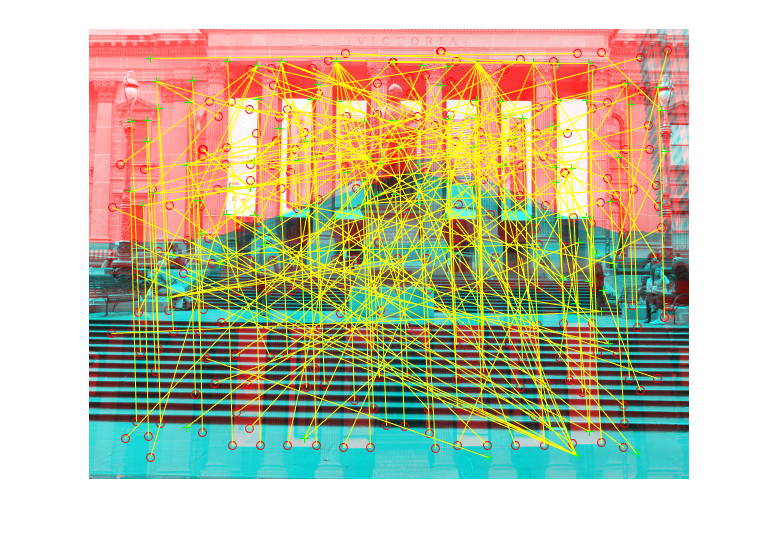

hprevImage =   Image with properties:

           CData: [450×600×3 uint8]
    CDataMapping: 'direct'

  Show all properties



    hprevImage = showMatchedFeatures(curr_img, next_img, [matchedp1X, matchedp1Y], [matchedp2X, matchedp2Y])

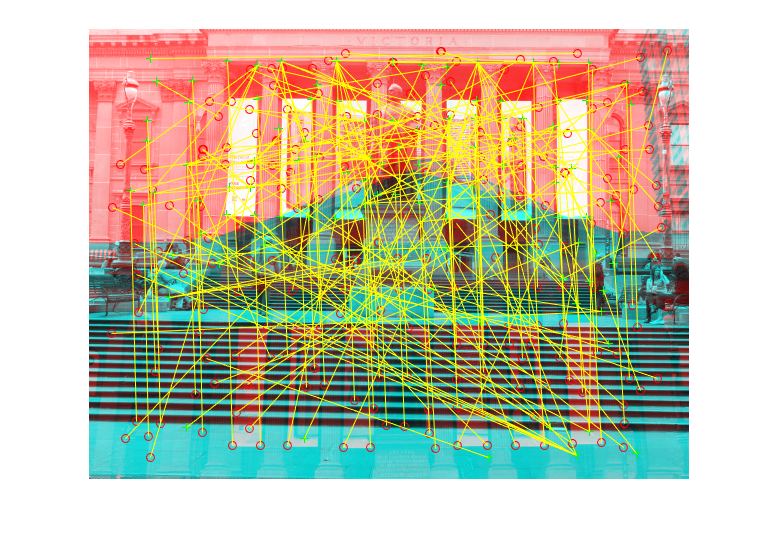

hImage =   Image with properties:

           CData: [450×600×3 uint8]
    CDataMapping: 'direct'

  Show all properties


    hImage = showMatchedFeatures(curr_img, next_img, [INLIERSp1X, INLIERSp1Y], [INLIERSp2X, INLIERSp2Y])

function [x_best, y_best] = ANMS(img, features, SHOW_OUTPUT)
    n_best = 300; 
    NStrong = 0;
    [y_size, x_size, ~] = size(img);
%    sz = size(img) 
    x_max = [];
    y_max = [];


    for x = 1:x_size
        for y = 1:y_size
            if features(y,x) == 1
                NStrong = NStrong + 1;
                x_max = [x_max x];
                y_max = [y_max y];  % array concatenation
            end
        end
    end
    
%     if SHOW_OUTPUT
%         % Plot features
%         imshow(img)
%         hold on
%         plot(features)
%         hold off
%     end
    
    r = Inf(1, NStrong);
    for i = 1:NStrong
        for j = 1:NStrong
            if SHOW_OUTPUT(y_max(j), x_max(j)) > SHOW_OUTPUT(y_max(i), x_max(i))
                ED = ((x_max(j) - x_max(i))^2) + ((y_max(j) - y_max(i))^2);
                if ED < r(i)
                    r(i) = ED;
                end
            end
        end
    end
    
    x_best = zeros(1, n_best);
    y_best = zeros(1, n_best);
    
    % lowest n_best points
    [~, I] = sort(r, 'descend');
    
%         x = x(idx(1:NBest));
%     y = y(idx(1:NBest));
    
    p = [x(:), y(:)];
    
    for i = 1:n_best
        indx = I(i);
        x_best(i) = x_max(indx);
        y_best(i) = y_max(indx);
    end
end

function displayANMS(img, x_best, y_best)
    figure
    imshow(img)
    hold on
%     plot(x_best, y_best, 'Color', 'r', 'Marker','.', 'LineStyle','-')
    plot(x_best, y_best, 'r.')
    hold off
end


function [descriptors] = feature_descriptors(img_grayscale, x_best, y_best)
    [~, n_best] = size(x_best);
    [y_size, x_size] = size(img_grayscale);
    descriptors = [];
    for i = 1:n_best
        % Patch is of size 41x41, so point is the actual center
        x = x_best(i);
        y = y_best(i);
        % TODO?
        if or(or(or(x <= 21, y<=21), x + 21> x_size), y + 21 > y_size)
            v = zeros(8*8,1);
            descriptors = [descriptors v];
            continue;
        end
        patch = img_grayscale(y-21:y+21, x-21:x+21);
        % Gaussian blur
        sig = 10;
        blurred = imgaussfilt(patch, sig);
        % Resize
        resized = imresize(blurred, [8 8]);
        % Reshape
        reshaped = double(reshape(resized, [64, 1]));
        % Now we need to standardize
        std_dev = std(reshaped);
        mean_reshaped = mean(reshaped);
        standardized = reshaped - mean_reshaped;
        standardized = standardized / std_dev;
        descriptors = [descriptors standardized];
    end
end


% fearture matching, first we need to make sure which points are matched
function [matchedDescriptors1, matchedDescriptors2, matchedp1X, matchedp1Y, matchedp2X, matchedp2Y] = getMatchedPoints(d1, d2, p1X, p1Y, p2X, p2Y, thresh)
    matchedp1X = [];
    matchedp1Y = [];
    matchedp2X = [];
    matchedp2Y = [];
    d1size = length(d1(1,:))
    d2size = length(d2(2,:))
    matchedDescriptors1 = [];
    matchedDescriptors2 = [];
    for i = 1:d1size
        for j = 1:d2size
            sumSquare(j) = sum((d1(:,i) - d2(:,j)).^2);
        end
        [sortedDist, I] = sort(sumSquare);
        ratio = sortedDist(1)/sortedDist(2);
        if (ratio < thresh)
            matchedDescriptors1 = [matchedDescriptors1, d1(:,i)];
            matchedDescriptors2 = [matchedDescriptors2, d2(:,I(1))];

            matchedp1X = [matchedp1X; p1X(i)];
            matchedp1Y = [matchedp1Y; p1Y(i)];

            matchedp2X = [matchedp2X; p2X(I(1))];
            matchedp2Y = [matchedp2Y; p2Y(I(1))];
        end
    end
end

function H = est_homography(X,Y,x,y)
    % H = est_homography(X,Y,x,y)
    % Compute the homography matrix from source(x,y) to destination(X,Y)
    %
    %    X,Y are coordinates of destination points
    %    x,y are coordinates of source points
    %    X/Y/x/y , each is a vector of n*1, n>= 4
    %
    %    H is the homography output 3x3
    %   (X,Y, 1)^T ~ H (x, y, 1)^T
    
    A = zeros(length(x(:))*2,9);
    
    for i = 1:length(x(:)),
     a = [x(i),y(i),1];
     b = [0 0 0];
     c = [X(i);Y(i)];
     d = -c*a;
     A((i-1)*2+1:(i-1)*2+2,1:9) = [[a b;b a] d];
    end
    
    [U S V] = svd(A);
    h = V(:,9);
    H = reshape(h,3,3)';
end

function [X, Y] = apply_homography(H, x, y)
    % [X, Y] = apply_homography(H, x, y)
    % Use homogrphay matrix H to compute position (x,y) in the source image to
    % the position (X,Y) in the destination image
    %
    % Input
    %   H : 3*3 homography matrix, refer to setup_homography
    %   x : the column coords vector, n*1, in the source image
    %   y : the column coords vector, n*1, in the source image
    % Output
    %   X : the column coords vector, n*1, in the destination image
    %   Y : the column coords vector, n*1, in the destination image
    
    p1 = [x'; y'; ones(1, length(x))];
    q1 = H*p1;
    q1 = q1./[q1(3, :); q1(3,:); q1(3, :)];
    
    X = q1(1,:)';
    Y = q1(2, :)';
end

function [H_ls, INLIERSp1X, INLIERSp1Y, INLIERSp2X, INLIERSp2Y] = RANSAC(N_max, thresh, matchedp1X, matchedp1Y, matchedp2X, matchedp2Y)
    
%     thresh = 1e3
    total = size(matchedp1X, 1); inliers_count = 0; iter = 0;
    INLIERSp1X = []; INLIERSp1Y = []; INLIERSp2X = []; INLIERSp2Y = [];
    INLIERSp1XY = []; INLIERSp2XY = []; INLIERSXY = [];
    
    while (iter < N_max || ((inliers_count/total) < 0.90))

        random_i = randi([1 total], 1, 4);
        % 1. Select four pairs of matched pixels (at random), 1<=i<=4, p_1i/p_2i from images 1/2.
        
        tempX1 = matchedp1X(random_i); tempY1 = matchedp1Y(random_i);
        tempX2 = matchedp2X(random_i); tempY2 = matchedp2Y(random_i);
        
        % 2. Compute the homography matrix from the four feature pairs using est_homography
        H = est_homography(tempX1,tempY1,tempX2,tempY2);
        
        % 3. Compute inliers where SSD(Hp_1, p_2) < threshold
        for i=1:4
%             p1 = [tempX1(i); tempY1(i); 1];
            p2 = [tempX2(i); tempY2(i)];
%             Hp1 = H*p1
            [Hp1X, Hp1Y] = apply_homography(H, [tempX1(i)], [tempY1(i)]);
            Hp1 = [Hp1X; Hp1Y];
            X = Hp1 - p2;
            ssd = sum(X(:).^2);
            if (ssd < thresh)
                
%                 fprintf("ssd: %f < thresh: %f\n", ssd, thresh);

%                 INLIERSp1X = [INLIERSp1X; tempX1(i)];
%                 INLIERSp1Y = [INLIERSp1Y; tempY1(i)];
%                 INLIERSp2X = [INLIERSp2X; tempX2(i)];
%                 INLIERSp2Y = [INLIERSp2Y; tempY2(i)];

%                 INLIERSp1XY = [INLIERSp1XY; [tempX1(i), tempY1(i)]];
%                 INLIERSp2XY = [INLIERSp2XY; [tempX2(i), tempY2(i)]];

                INLIERSXY = [INLIERSXY; [tempX1(i), tempY1(i), tempX2(i), tempY2(i)]];
                
%                 if (size(INLIERSp1XY, 1) > 1)
%                 disp("========================================================================================")
%                 disp("INLIERSp1XY: ")
%                 disp(INLIERSp1XY)
%                 end
                
%                 INLIERSp1XY = unique(INLIERSp1XY, 'rows', 'stable');
%                 INLIERSp2XY = unique(INLIERSp2XY, 'rows', 'stable');
                INLIERSXY = unique(INLIERSXY, 'rows', 'stable');
                
%                 inliers_count = inliers_count + 1
                inliers_count = size(INLIERSXY,1);
            end
        end
        % 4. Repeat the last 3 steps until you reach N_max iters or 90% of inliers.
        iter = iter + 1;
%         N_max
%         if (iter > 200)
%             fprintf('')
%         end
        % 5. Keep largest set of inliers.
    end

    % https://www.mathworks.com/matlabcentral/answers/373747-find-unique-in-matrix-of-x-y-coordinates
%     INLIERSp1XY = [INLIERSp1X, INLIERSp1Y]
%     INLIERSp2XY = [INLIERSp2X, INLIERSp2Y]
%     uniqueINLIERSp1XY = unique(INLIERSp1XY, 'rows', 'stable')
%     uniqueINLIERSp2XY = unique(INLIERSp2XY, 'rows', 'stable')

    % 6. Recompute least-square H on all inliers.
%     H_ls = est_homography(INLIERSp1XY(:,1),INLIERSp1XY(:,2),INLIERSp2XY(:,1),INLIERSp2XY(:,2))
    
    H_ls = est_homography(INLIERSXY(:,1),INLIERSXY(:,2),INLIERSXY(:,3),INLIERSXY(:,4))
    
    INLIERSp1X = INLIERSXY(:,1)
    INLIERSp1Y = INLIERSXY(:,2)
    INLIERSp2X = INLIERSXY(:,3)
    INLIERSp2Y = INLIERSXY(:,4)
    
    fprintf("end RANSAC");

    
end

function hImage = showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, varargin)
%showMatchedFeatures Display corresponding feature points.
%  showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2) displays a
%  falsecolor overlay of images I1 and I2, with a color-coded plot of the
%  corresponding points connected by a line. matchedPoints1 and
%  matchedPoints2 are the coordinates of corresponding points in I1 and
%  I2. Points can be an M-by-2 matrix of [x y] coordinates, a SURFPoints
%  an MSERRegions, a cornerPoints, or a BRISKPoints object.
%
%  showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2, method)
%  displays images I1 and I2 using the visualization style specified by
%  method. Values of method can be:
%
%    'falsecolor' : Overlay the images by creating a composite red-cyan 
%                   image showing I1 as red and I2 as cyan.
%    'blend'      : Overlay I1 and I2 using alpha blending.
%    'montage'    : Place I1 and I2 next to each other in the same image.
%
%    Default: 'falsecolor'
%
%  hImage = showMatchedFeatures(...) returns the handle to the image object
%  returned by showMatchedFeatures.
%
%  showMatchedFeatures(...,Name,Value) specifies additional name-value pair 
%  arguments described below:
%
%  'PlotOptions'  Specify custom plot options in a cell array containing 
%                 three string values, {MarkerStyle1, MarkerStyle2, LineStyle},
%                 corresponding to marker specification in I1, marker 
%                 specification in I2, and line style and color. Each of 
%                 the specifiers is defined by the LineSpec of PLOT function.
%
%                 Default: {'ro','g+','y-'}
%
%   'Parent'      Specify an output axes for displaying the visualization.
%
%  Class Support
%  -------------
%  I1 and I2 are numeric arrays.
%
%  Example 1
%  ---------
%  % Use Harris features to find corresponding points between two images.
%  I1 = rgb2gray(imread('parkinglot_left.png'));
%  I2 = rgb2gray(imread('parkinglot_right.png'));
%
%  points1 = detectHarrisFeatures(I1);
%  points2 = detectHarrisFeatures(I2);
%   
%  [f1, vpts1] = extractFeatures(I1, points1);
%  [f2, vpts2] = extractFeatures(I2, points2);
%
%  indexPairs = matchFeatures(f1, f2) ;
%  matchedPoints1 = vpts1(indexPairs(1:20, 1));
%  matchedPoints2 = vpts2(indexPairs(1:20, 2));
%
%  % Visualize putative matches
%  figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2,'montage');
%
%  title('Putative point matches');
%  legend('matchedPts1','matchedPts2');
%
%  Example 2
%  ---------
%  % Use SURF features to find corresponding points between two images
%  % rotated and scaled with respect to each other
%  I1 = imread('cameraman.tif');
%  I2 = imresize(imrotate(I1,-20), 1.2);
% 
%  points1 = detectSURFFeatures(I1);
%  points2 = detectSURFFeatures(I2);
% 
%  [f1, vpts1] = extractFeatures(I1, points1);
%  [f2, vpts2] = extractFeatures(I2, points2);
%         
%  indexPairs = matchFeatures(f1, f2) ;
%  matchedPoints1 = vpts1(indexPairs(:, 1));
%  matchedPoints2 = vpts2(indexPairs(:, 2));
%
%  % Visualize putative matches
%  figure; showMatchedFeatures(I1,I2,matchedPoints1,matchedPoints2);
%
%  title('Putative point matches');
%  legend('matchedPts1','matchedPts2');
%
% See also matchFeatures, estimateGeometricTransform, imshowpair,
%     legend, SURFPoints, MSERRegions, cornerPoints

% Copyright 2011 The MathWorks, Inc.

narginchk(4,7);
 
[matchedPoints1, matchedPoints2, method, lineSpec, hAxes] = ...
    parseInputs(I1, I2, matchedPoints1, matchedPoints2, varargin{:});

% pad the smaller image
paddedSize = [max(size(I1,1), size(I2,1)), max(size(I1,2), size(I2,2))];
I1pad = [paddedSize(1) - size(I1,1), paddedSize(2) - size(I1,2)];
I2pad = [paddedSize(1) - size(I2,1), paddedSize(2) - size(I2,2)];
I1pre = round(I1pad/2);
I2pre = round(I2pad/2);
I1 = padarray(I1, I1pre, 0, 'pre');
I2 = padarray(I2, I2pre, 0, 'pre');
I1 = padarray(I1, I1pad-I1pre, 0, 'post');
I2 = padarray(I2, I2pad-I2pre, 0, 'post');

switch lower(method)
    case {'falsecolor'}
        imgOverlay = imfuse(I1, I2);
        % create red-cyan image instead of the imfuse default
        imgOverlay(:,:,1) = imgOverlay(:,:,2);
        imgOverlay(:,:,2) = imgOverlay(:,:,3);
    case {'blend'}
        imgOverlay = imfuse(I1,I2,'blend');        
    case {'montage'}
        imgOverlay = imfuse(I1,I2,'montage');
end

% Display the composite image
if nargout > 0
    hImage = imshow(imgOverlay, 'Parent', hAxes);
else
    imshow(imgOverlay, 'Parent', hAxes);
end

holdState = get(hAxes,'NextPlot'); % store the state for 'hold' before changing it
set(hAxes, 'NextPlot', 'add');

%============
% Plot points
%============
% Calculate the offsets needed to adjust plot after images were fused
offset1 = fliplr(I1pre);
offset2 = fliplr(I2pre);
if strcmp(method, 'montage')
    offset2 = offset2 + fliplr([0 size(I1,2)]);
end

matchedPoints1 = bsxfun(@plus, matchedPoints1, offset1);
matchedPoints2 = bsxfun(@plus, matchedPoints2, offset2);

if ~isempty(lineSpec{1})
    plot(hAxes, matchedPoints1(:,1), matchedPoints1(:,2), lineSpec{1}); % marker 1
end
if ~isempty(lineSpec{2})
    plot(hAxes, matchedPoints2(:,1), matchedPoints2(:,2), lineSpec{2}); % marker 2
end

% Plot by using a single line object with line segments broken by using
% NaNs. This is more efficient and makes it easier to customize the lines.
lineX = [matchedPoints1(:,1)'; matchedPoints2(:,1)'];
numPts = numel(lineX);
lineX = [lineX; NaN(1,numPts/2)];

lineY = [matchedPoints1(:,2)'; matchedPoints2(:,2)'];
lineY = [lineY; NaN(1,numPts/2)];

plot(hAxes, lineX(:), lineY(:), lineSpec{3}); % line

set(hAxes, 'NextPlot', holdState); % restore the hold state

drawnow();
end

%==========================================================================
% Input parser
%==========================================================================
function [matchedPoints1, matchedPoints2, method, lineSpec, hAxes] = ...
    parseInputs(I1, I2, matchedPoints1, matchedPoints2, varargin)

% do only basic image validation; let padarray and imfuse take care of 
% the rest
validateattributes(I1,{'numeric','logical'},{'real','nonsparse',...
    'nonempty'},mfilename,'I1',1)
validateattributes(I2,{'numeric','logical'},{'real','nonsparse',...
    'nonempty'},mfilename,'I2',2)

matchedPoints1 = parsePoints(matchedPoints1, 1);
matchedPoints2 = parsePoints(matchedPoints2, 2);

if size(matchedPoints1,1) ~= size(matchedPoints2,1)
    error(message('vision:showMatchedFeatures:numPtsMustMatch'));
end

% Process the rest of inputs
parser = inputParser;
parser.FunctionName  = mfilename;

parser.addOptional('Method', 'falsecolor', @checkMethod);
parser.addParameter('PlotOptions', {'ro','g+','y-'}, @checkPlotOptions);
parser.addParameter('Parent', [], ...
    @vision.internal.inputValidation.validateAxesHandle);

% Parse inputs
parser.parse(varargin{:});

% Calling validatestring again permits easy handling of partial string matches
method = validatestring(parser.Results.Method,...
    {'falsecolor','blend','montage'},mfilename,'Method');

lineSpec = parser.Results.PlotOptions;

hAxes = newplot(parser.Results.Parent);
end

%==========================================================================
function points=parsePoints(points, ptsInputNumber)

fcnInputVarNumber = 2 + ptsInputNumber; 
varName = ['matchedPoints', num2str(ptsInputNumber)];

if ~isa(points, 'vision.internal.FeaturePoints') && ~isa(points, 'MSERRegions')
    validateattributes(points,{'int16', 'uint16', 'int32', 'uint32', ...
        'single', 'double'}, {'2d', 'nonsparse', 'real', 'size', [NaN 2]},...
        mfilename, varName, fcnInputVarNumber);
else
    points = points.Location;
end

points = double(points);
end

%==========================================================================
function tf = checkMethod(method)

validatestring(method,{'falsecolor','blend','montage'},mfilename,'Method');

tf = true;
end

%==========================================================================
function tf = checkPlotOptions(options)

validateattributes(options,{'cell'}, {'size', [1 3]},...
    mfilename, 'PlotOptions');

validateattributes(options{1},{'char'},{},mfilename,'MarkerStyle1');
validateattributes(options{2},{'char'},{},mfilename,'MarkerStyle2');
validateattributes(options{3},{'char'},{},mfilename,'LineStyle');

% Now check valid strings
checkMarkerStyle(options{1}, 1);
checkMarkerStyle(options{2}, 2);

checkLineStyle(options{3});

tf = true;
end
%==========================================================================
function style=eliminateColorSpec(style)

colorSpec = cell2mat({'r','g','b','c','m','y','k','w'});

% Color can be specified only at the beginning or end of the style string.
% Look for only one specifier. If color was specified twice, it will cause
% a failure in later stages of parsing
if ~isempty(style)
    if isempty(strfind(colorSpec, style(1)))
        % try the other end
        if ~isempty(strfind(colorSpec, style(end)))
            style(end) = [];
        end
    else
        style(1) = [];
    end
end
end
%==========================================================================
function checkMarkerStyle(style, id)

style = strtrim(style); % remove blanks from either end of the string
style = strtrim(eliminateColorSpec(style)); % pull out valid color spec

if isempty(style)
   % permit empty marker style, which amounts to marker not being displayed 
else
    markerSpec = {'+','o','*','.','x','square','s','diamond','d','^',...
        'v','>','<','pentagram','p','hexagram','hImage'};
    
    try
        validatestring(style,markerSpec);
    catch %#ok<CTCH>
        error(message('vision:showMatchedFeatures:invalidMarkerStyle',id));
    end
end
end
%==========================================================================
function checkLineStyle(style)

style = strtrim(style); % remove blanks from either end of the string
style = strtrim(eliminateColorSpec(style)); % pull out valid color spec

if isempty(style)
    % permit empty line style thus letting plot use its default settings
else
    lineSpec = {'-','--',':','-.'};
    
    try
        validatestring(style,lineSpec);
    catch %#ok<CTCH>
        error(message('vision:showMatchedFeatures:invalidLineStyle'));
    end
end
end